# Example 11.1: `Four-Channel ``TDOA`` Solution` 

Nicholas O'Donoughue 1 July 2019

`Consider an example four-channel ``TDOA`` system with three sensors equally spaced along a 10-km radius circle, centered on a reference sensor. The locations are plotted in Figure 11.7. In this example, there is an emitter roughly 50 km from the central reference center, marked with a triangle. We assume that each sensor achieves a standard deviation of 100 ``ns`` on ``TOA`` estimation. Generate solutions from a single set of timing measurements at the four sensors, using each of the approaches discussed in this chapter.`

## Solution

`We begin by defining the sensor and source positions`

% Define Sensor Positions
baseline        = 10e3; % meters
num_sensors     = 4;
sensor_rotation = pi/2; % rotation angle of sensor constellaion
sensor_pos_angle = (0:num_sensors-1)*2*pi/(num_sensors-1) + pi/2; 
x_sensor = baseline* [ cos(sensor_pos_angle);sin(sensor_pos_angle)];

% Move the first sensor to the origin
x_sensor(:,1) = 0;

% Define Sensor Performance
timingError    = 1e-7; % s
idx_ref_sensor = 1; assert(idx_ref_sensor <= num_sensors,'Bad reference sensor index.');
C_toa = timingError^2 * eye(num_sensors); % TOA covariance matrix
C_roa = utils.constants.c^2*C_toa; % ROA covariance matrix
C_tdoa = utils.resampleCovMtx(C_toa,idx_ref_sensor); % TDOA
C_rdoa = utils.resampleCovMtx(C_roa,idx_ref_sensor); % Convert to RDOA

% Initialize Transmitter Position
source_angle = rand(1)*2*pi;
source_baseline_multiplier = 5;
x_source = source_baseline_multiplier*baseline*[cos(source_angle);sin(source_angle)];

`Next, we generate a set of range difference measurements.`

% Compute Range
% R = sqrt(sum(abs(x_source-x_sensor).^2,1)); % Range to each sensor [m]
dR = tdoa.measurement(x_sensor,x_source,idx_ref_sensor);

% Generate Range Measurements
num_monte_carlo = 10;
L = chol(C_rdoa,'lower'); % cholesky decomposition of covariance matrix
num_msmt = size(L,1);
noise = L * randn(num_msmt,num_monte_carlo); % range-difference msmt noise
rho_mc = dR + noise; % Noisy sample vector

% Check covariance of rho
check_noise_covar = true;
if check_noise_covar
    mu_rho = mean(rho_mc,2);
    cov_rho = cov(rho_mc.');
    
    fprintf('Desired C:\n');
    C_rdoa
    fprintf('Actual C:\n');
    cov_rho
    fprintf('Error (normalized):\n');
    (C_rdoa-cov_rho)./cov_rho
end

Desired C:


C_rdoa = 	1.0e+03 *

    1.7975    0.8988    0.8988
    0.8988    1.7975    0.8988
    0.8988    0.8988    1.7975


Actual C:


cov_rho = 	1.0e+03 *

    1.8318    1.5643    1.1634
    1.5643    2.5247    1.4216
    1.1634    1.4216    1.9508


Error (normalized):


ans =    -0.0187   -0.4254   -0.2274
   -0.4254   -0.2880   -0.3678
   -0.2274   -0.3678   -0.0786


`Then, for each of the Monte Carlo iterations, we call the ``TDOA`` solvers and store the estimated source positions.`

% Initial Target Position Estimate
init_angle_offset = pi/6;
init_baseline_mult = 2;
init_angle = source_angle + init_angle_offset;
init_baseline = init_baseline_mult*baseline;
x_init = init_baseline*[cos(init_angle);sin(init_angle)];

% Call the TDOA solution algorithms
epsilon =       0.01; % Stopping condition for iterative solvers
numIters =      100; % Maxinum number of iterations for iterative solvers
alpha =         0.3; % Parameter for gradient descent
beta =          0.6; % Parameter for gradient descent
search_size =  [50; 50]; % Search Grid Size
grid_res =      100; % Resolution of the search grid

x_ls = zeros(2,numIters,num_monte_carlo);
x_grad = zeros(2,numIters,num_monte_carlo);
x_chanHo = zeros(2,num_monte_carlo);
x_bf = zeros(2,num_monte_carlo);

fprintf('Performing Monte Carlo simulation...\n');

Performing Monte Carlo simulation...


for idx = 1:num_monte_carlo
    if mod(idx,floor(num_monte_carlo/100))==0
        fprintf('.');
    end
    
    rho = rho_mc(:,idx); % grab current measurement

    % Compute solutions
    [~,x_ls(:,:,idx)] = tdoa.lsSoln(x_sensor,rho,C_roa,x_init,[],numIters,true,[],idx_ref_sensor);    
    [~,x_grad(:,:,idx)] = tdoa.gdSoln(x_sensor,rho,C_roa,x_init,alpha,beta,[],numIters,true,[],idx_ref_sensor);
    x_chanHo(:,idx) = tdoa.chanHoSoln(x_sensor,rho,C_roa,idx_ref_sensor);
    x_bf(:,idx) = tdoa.bfSoln(x_sensor,rho,C_roa,x_init,5*baseline,grid_res,idx_ref_sensor);
end
fprintf('done.\n');

done.


After completing the trials, we compute the error for each estimate, the bias across the Monte Carlo trials, and the RMSE across the Monte Carlo trials.

err_ls = x_source - x_ls;
err_grad = x_source - x_grad;
err_bf = x_source - x_bf;
err_chanHo = x_source - x_chanHo;

bias_bf = mean(err_bf,2);
bias_chanHo = mean(err_chanHo,2);

cov_bf = cov(err_bf')+bias_bf*bias_bf';
cov_chanHo = cov(err_chanHo')+bias_chanHo*bias_chanHo';
cep50_bf = utils.computeCEP50(cov_bf)/1e3; % km
cep50_chanHo = utils.computeCEP50(cov_chanHo)/1e3; % km

bias_ls = zeros(2,numIters);
bias_grad = zeros(2,numIters);
cov_ls = zeros(2,2,numIters);
cov_grad = zeros(2,2,numIters);
cep50_ls = zeros(1,numIters);
cep50_grad = zeros(1,numIters);
for ii=1:numIters
    bias_ls(:,ii) = mean(squeeze(err_ls(:,ii,:)),2);
    bias_grad(:,ii) = mean(squeeze(err_grad(:,ii,:)),2);
    
    cov_ls(:,:,ii) = cov(squeeze(err_ls(:,ii,:))') + bias_ls(:,ii)*bias_ls(:,ii)';
    cov_grad(:,:,ii) = cov(squeeze(err_grad(:,ii,:))') + bias_grad(:,ii)*bias_grad(:,ii)';
    
    cep50_ls(ii) = utils.computeCEP50(cov_ls(:,:,ii))/1e3; % [km]
    cep50_grad(ii) = utils.computeCEP50(cov_grad(:,:,ii))/1e3; % [km]
end
% Compute CRLB RMSE
err_crlb = tdoa.computeCRLB(x_sensor,x_source,Ctdoa);
crlb_cep50 = utils.computeCEP50(err_crlb)/1e3; % [km]
crlb_ellipse = utils.drawErrorEllipse(x_source,err_crlb,100,90);

## `First Subfigure`

`The sensor and emitter positions are plotted below, along with iterative position estimates using both the least squares and gradient descent algorithms presented, and the 90% error ellipse predicted from the CRLB.`

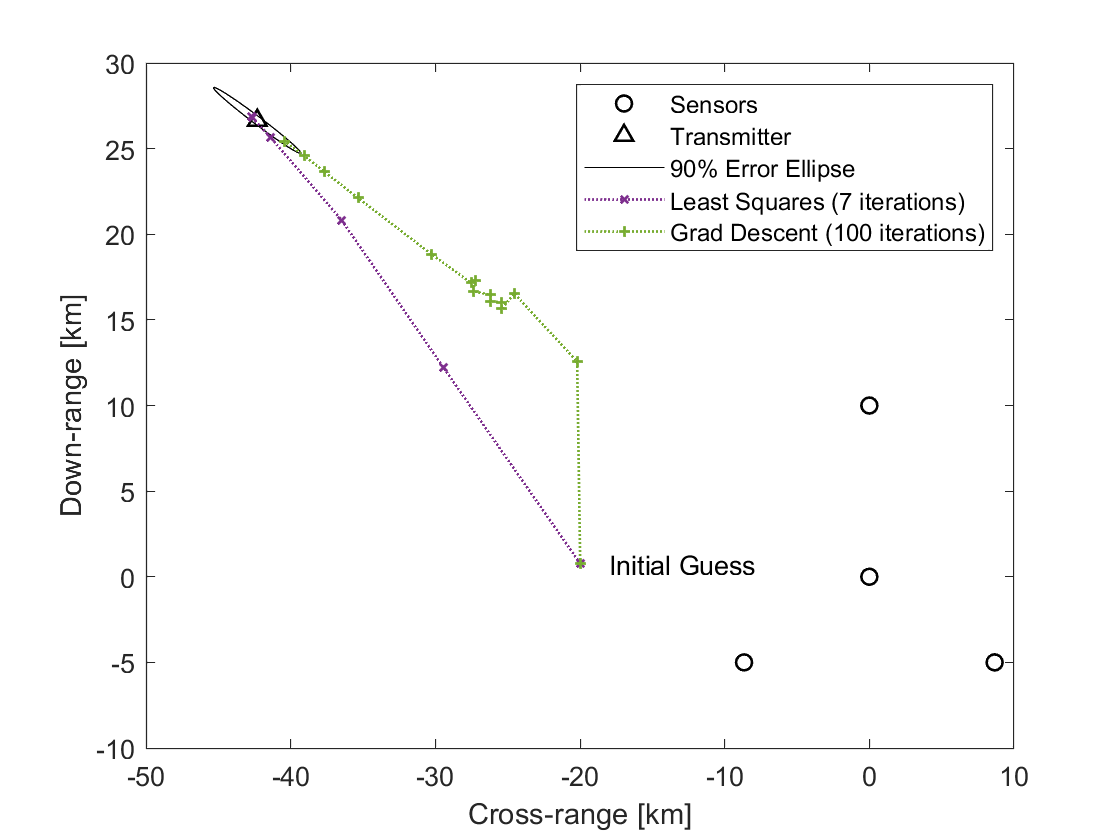

% Subsample iterative solutions for plotting
plotIndex = [1:10,20:20:100,200:200:numIters];
x_ls_plot = x_ls(:,plotIndex,1);
x_grad_plot = x_grad(:,plotIndex,1);

% Plot Geometry
numIterToPlot=min(20,numel(plotIndex));
fig_geo_a=figure;
plot(x_sensor(1,:)/1e3,x_sensor(2,:)/1e3,'ko','DisplayName','Sensors','LineWidth',1);
hold on;
plot(x_source(1,:)/1e3,x_source(2,:)/1e3,'k^','DisplayName','Transmitter','LineWidth',1);
plot(crlb_ellipse(1,:)/1e3,crlb_ellipse(2,:)/1e3,'k','LineWidth',.5,'DisplayName','90% Error Ellipse');
plot(x_ls_plot(1,1:floor(numIterToPlot/2),1)/1e3,x_ls_plot(2,floor(1:numIterToPlot/2),1)/1e3,':x','DisplayName',sprintf('Least Squares (%d iterations)',plotIndex(floor(numIterToPlot/2))),'LineWidth',1,'MarkerSize',4);
plot(x_grad_plot(1,1:numIterToPlot,1)/1e3,x_grad_plot(2,1:numIterToPlot,1)/1e3,':+','DisplayName',sprintf('Grad Descent (%d iterations)',plotIndex(numIterToPlot)),'LineWidth',1,'MarkerSize',4);
set(gca,'ColorOrderIndex',3);

% Label Solutions
text(x_init(1)/1e3+2,x_init(2)/1e3,'Initial Guess','FontSize',10);
% text(mean(x_ls_plot(1,1:2,1))/1e3+5,mean(x_ls_plot(2,1:2,1))/1e3,'Least Squares','FontSize',10);
% text(x_grad_plot(1,2,1)/1e3-40,x_grad_plot(2,2,1)/1e3,'Gradient Descent','FontSize',10);
xlabel('Cross-range [km]');ylabel('Down-range [km]');
legend('Location','NorthEast');
grid off;

## Second Subfigure

This figure is a zoomed in replication of the first figure; focused on the transmitter area.  In addition to the two iterative solvers, we also plot the solutions for one trial using the Bestfix and Chan-Ho solvers.

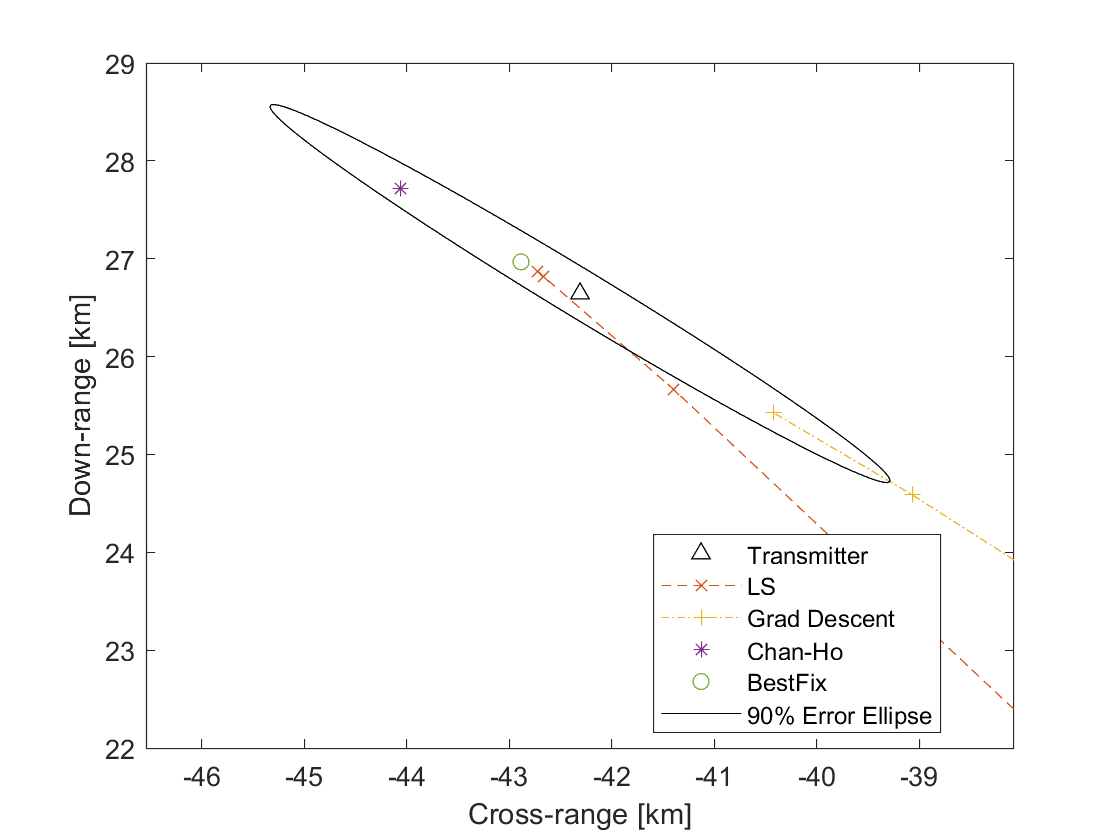

% Plot zoomed geometry
fig_geo_b=figure;
plot(x_source(1,:)/1e3,x_source(2,:)/1e3,'k^','DisplayName','Transmitter');
hold on;
plot(x_ls_plot(1,1:floor(numIterToPlot/2),1)/1e3,x_ls_plot(2,1:floor(numIterToPlot/2),1)/1e3,'--x','DisplayName','LS');
plot(x_grad_plot(1,1:numIterToPlot,1)/1e3,x_grad_plot(2,1:numIterToPlot,1)/1e3,'-.+','DisplayName','Grad Descent');
plot(x_chanHo(1,1)/1e3,x_chanHo(2,1)/1e3,'*','DisplayName','Chan-Ho');
plot(x_bf(1,1)/1e3,x_bf(2,1)/1e3,'o','DisplayName','BestFix');

plot(crlb_ellipse(1,:)/1e3,crlb_ellipse(2,:)/1e3,'k','LineWidth',.5,'DisplayName','90% Error Ellipse');

wd = 1.4*max(abs(crlb_ellipse(1,:)-x_source(1)));
% ht=wd*7/8;
% ylim([-1 1]*ht/1e3+x_source(2)/1e3);
xlim([-1 1]*wd/1e3+x_source(1)/1e3);
xlabel('Cross-range [km]');ylabel('Down-range [km]');
legend('Location','best');
grid off;

## Third Subfigure

In this figure, we plot the CEP50, computed from the error (both covariance and bias) for each of the solvers, across the Monte Carlo trials.

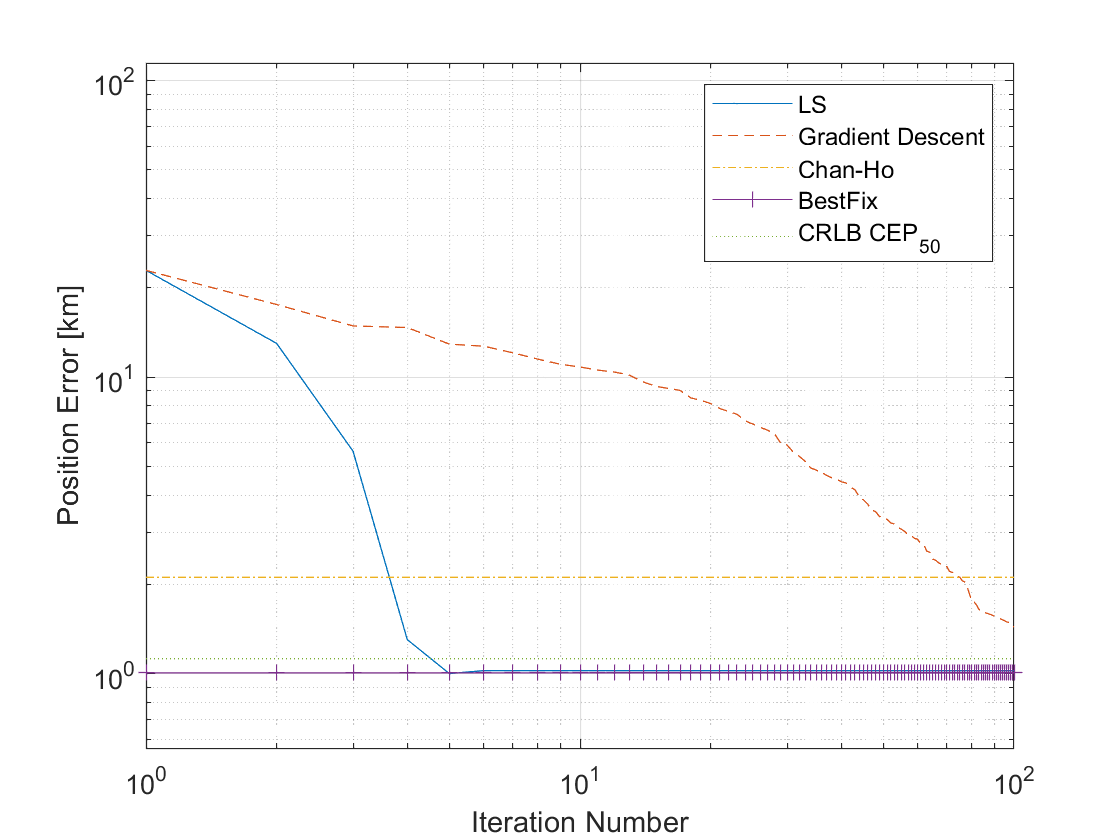

fig_err=figure;
plot(1:numIters,cep50_ls,'DisplayName','LS');
hold on;
plot(1:numIters,cep50_grad,'--','DisplayName','Gradient Descent');
plot(1:numIters,cep50_chanHo*ones(1,numIters),'-.','DisplayName','Chan-Ho');
plot(1:numIters,cep50_bf*ones(1,numIters),'-+','DisplayName','BestFix');
plot(1:numIters,crlb_cep50*ones(1,numIters),':','DisplayName','CRLB CEP_{50}');
xlabel('Iteration Number');
ylabel('Position Error [km]');
set(gca,'yscale','log');
set(gca,'xscale','log');
% text(22,15,'Gradient Descent','FontSize',10);
% text(4,6,'Least Square','FontSize',10);
% text(1.5,1.8,'Chan-Ho','FontSize',10);
% text(1.5,1.2,'CRLB $CEP_{50}$','FontSize',10);
legend('Location','NorthEast');
ylim([crlb_cep50*.5 2*max(cep50_ls)]);
grid on;